clc;
close all;
clearvars;
% Lag Compensator Design
plant_num = 5;
plant_den = [2 1 0];
plant_tf = tf(plant_num,plant_den);
comp_num = [1 4];
comp_den = [1 16 76 96];
comp_tf = tf(comp_num,comp_den);
% Plotting Gain and Phase margin for plant
figure;
margin(plant_tf);
grid on;
% Compensated System
lag_comp_sys = plant_tf*comp_tf;
disp(lag_comp_sys);

  tf with properties:

       Numerator: {[0 0 0 0 5 20]}
     Denominator: {[2 33 168 268 96 0]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



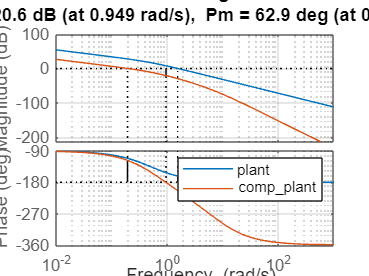

hold on;
margin(lag_comp_sys);
legend ('plant', 'comp_plant');

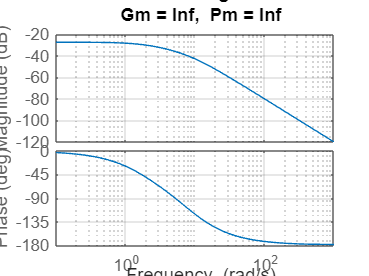

% Plotting Gain and Phase margin for compensator
figure;
margin(comp_tf);
grid on;